# Modelo SIR 

## Variables

## 
$$             

\textit{N = S+I+R}\\
\textit{1. S - Los susceptibles de enterarse del chisme}\\
\textit{2. I - Los infectados (chismosos) }\\
\textit{3. R - Recuperados de la infección (ya no creen en el chisme).}$$


## Modelo

Ecuaciones que gobiernan la dinámica del modelo:

## 
$$\frac{dS}{dt} = -\beta \textit{ S I} \\
\frac{dI}{dt} =  \rho \beta \textit{ S I} -\gamma \text{ I}+ \alpha \text{ R} +\textit{u}\\
\frac{dR}{dt}= \gamma \textit{ I} -\alpha\textit{ R}+(1-\rho)\beta \textit{ S I}$$


## Donde:

### 
$$\beta : \text{la tasa a la que se difunde el rumor}\\
(1-\rho) : \text{el porcentaje de la población que rechaza el rumor con solo oírlo} \\
\gamma : \text{la tasa a la que los infectados rechazan el rumor}\\
\alpha : \text{la tasa de persuasión de los Infectados sobre los Recuperados}$$


Todas las conlusiones de los análisis se presentan en el informe, además de que todo lo incluido en la carpeta es utilizado, la [imagen](matlab:open('./regina.png')) del modelo orginal, el [modelo verificado](matlab:open('./modelo_verificado.slx')), el cuál se utiliza para válidar que lo modelado se consistente respecto al orginal y el [modelo](matlab:open('./entradas.slx')) para realizar la experimentación, el cuál incluye una entrada la cuál se irá variando con fines de entender el sistema.

# **Modelo verificado**

Se utiliza el ejemplo **Regina George** que utilizan en el [The Mathematics of Gossip](https://scholarship.claremont.edu/codee/vol12/iss1/7/), replicamos los resultados y con base en ese se hacen los otros análisis.

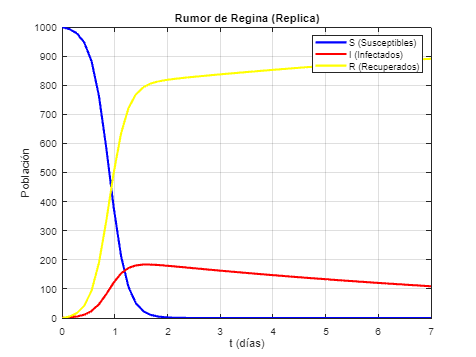

beta = 0.03; gamma = 0.1; rho = 0.2; alpha = 0.; 
N = 1000;I0 = 1; S0 = N-I0;  R0 = 0;
Days = 7;
out=sim('modelo_verificado.slx', Days);
figure
plot(out.tout, out.simS.Data, 'b', 'LineWidth', 2) 
hold on
grid on
plot(out.tout, out.simI.Data, 'r', 'LineWidth', 2) 
plot(out.tout, out.simR.data, 'y', 'LineWidth', 2) 
xlabel('t (días)');
ylabel('Población');
legend({'S (Susceptibles)', 'I (Infectados)', 'R (Recuperados)'});
title("Rumor de Regina (Replica)");
hold off;

#### Original

Esta imagen viene del [repositorio](https://github.com/izabelaguiar/The-Mathematics-of-Gossip/blob/master/The%20Mathematics%20of%20Gossip.ipynb) orginal y la tomamos para verificar que el modelo este funcionando acorde a lo esperado.

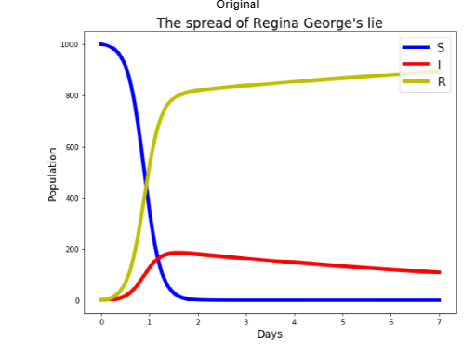

reginaImage = imread('regina.png');
figure;
imshow(reginaImage, 'InitialMagnification', 'fit');
title("Original");
set(gca, 'Position', [0, 0, 1, 1]);

## **Comparación Simulado vs Original**

Hacemos la comparación una al lado de la otra para que sea más fácil de leer, y efectivamente se vea la verificación.

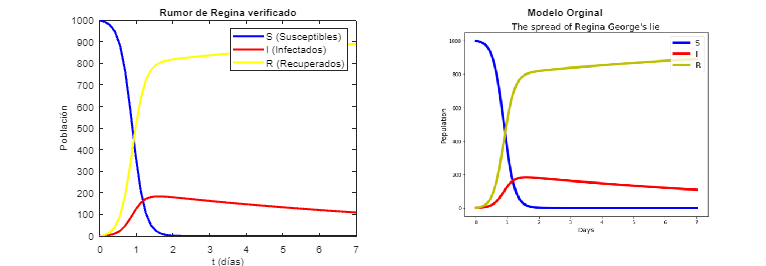

reginaImage = imread('regina.png');
beta = 0.03; gamma = 0.1; rho = 0.2; alpha = 0.; 
N = 1000;I0 = 1; S0 = N-I0;  R0 = 0;
Days = 7;
out=sim('modelo_verificado.slx', Days);
[imHeight, imWidth, ~] = size(reginaImage);
figure;
subplot(1, 2, 1); 
plot(out.tout, out.simS.Data, 'b', 'LineWidth', 2);
hold on;
plot(out.tout, out.simI.Data, 'r', 'LineWidth', 2);
plot(out.tout, out.simR.Data, 'y', 'LineWidth', 2);
xlabel('t (días)');
ylabel('Población');
legend({'S (Susceptibles)', 'I (Infectados)', 'R (Recuperados)'});
title("Rumor de Regina verificado");
subplot(1, 2, 2);
imshow(reginaImage, 'InitialMagnification', 'fit');
title("Modelo Orginal");
set(gcf, 'Position', [100, 100, imWidth * 2, imHeight]);
pos = get(subplot(1, 2, 2), 'Position');
set(subplot(1, 2, 2), 'Position', [pos(1) - 0.05, pos(2), pos(3) + 0.1, pos(4)]);
set(findall(gcf,'-property','FontSize'),'FontSize',10); 

# **Diferentes entradas**

**Acá se utiliza el archivo de simulink con entradas y se pruebam 4 entradas difrentes:**

En el informe se detallan los resultados, sin embargo, la entrada constante fue un experimento para entender el comportamiento del sistema.

## **Entrada constante**

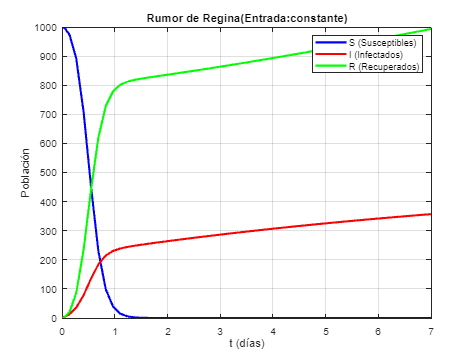

%Parametros
beta = 0.03; gamma = 0.1; rho = 0.2; alpha = 0.; 
N = 1000; I0 = 1; R0 = 0; S0 = N-I0;
u=50*ones(N,2); 
Days = 7;
out=sim('entradas.slx', Days);
figure;
plot(out.tout, out.sus.Data, 'b', 'LineWidth', 2);
hold on;
grid on;
plot(out.tout, out.inft.Data, 'r', 'LineWidth', 2);
plot(out.tout, out.recover.data, 'g', 'LineWidth', 2);
xlabel('t (días)');
ylabel('Población');
legend({'S (Susceptibles)', 'I (Infectados)', 'R (Recuperados)'});
title("Rumor de Regina(Entrada:constante)");
hold off;

## Entrada sinusoidal 

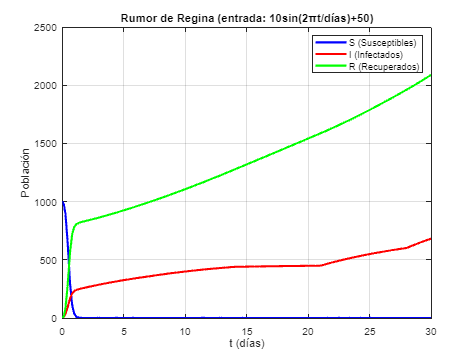

%Parametros
beta = 0.03; gamma = 0.1; rho = 0.2; alpha = 0.;
N = 1000; I0 = 1; R0 = 0;  S0 = N-I0;
Days = 15;
h = Days/N;
t = 0:h:Days;
sinusoidal_input = 10*sin(2*pi*t/Days)+50;
inputData.time = t';
inputData.signals.values = sinusoidal_input'; 
inputData.signals.dimensions = 1;
u = inputData;
out=sim('entradas.slx', 30);
figure;
plot(out.tout, out.sus.Data, 'b', 'LineWidth', 2); 
hold on;
grid on;
plot(out.tout, out.inft.Data, 'r', 'LineWidth', 2);
plot(out.tout, out.recover.data, 'g', 'LineWidth', 2); 
xlabel('t (días)');
ylabel('Población');
legend({'S (Susceptibles)', 'I (Infectados)', 'R (Recuperados)'});
title("Rumor de Regina (entrada: 10sin(2πt/días)+50)");
hold off;

## Entrada pulso

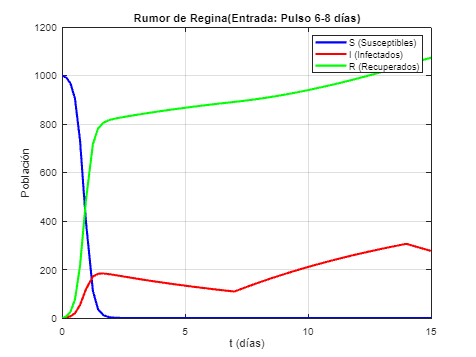

% Parámetros
beta = 0.03; gamma = 0.1; rho = 0.2; alpha = 0;
N = 1000; I0 = 1; R0 = 0; S0 = N-I0;
Days = 15;
t = 0:0.01:Days;
u_pulse = zeros(size(t)); 
start_pulse_day = 6;  
end_pulse_day= 8;
u_pulse(t >= start_pulse_day & t<= end_pulse_day) = 50;
inputData.time = t';
inputData.signals.values = u_pulse';
inputData.signals.dimensions = 1;
u = inputData;
out = sim('entradas.slx',Days);
% Grafica
figure;
plot(out.tout, out.sus.Data, 'b', 'LineWidth', 2);
hold on;
grid on;
plot(out.tout, out.inft.Data, 'r', 'LineWidth', 2);
plot(out.tout, out.recover.data, 'g', 'LineWidth', 2);
xlabel('t (días)');
ylabel('Población');
legend({'S (Susceptibles)', 'I (Infectados)', 'R (Recuperados)'});
title("Rumor de Regina(Entrada: Pulso 6-8 días)");
hold off;

**Señalización de pulso:**

Esto se hace para que el lector entienda en qué parte está, solo por fines metodológicos.

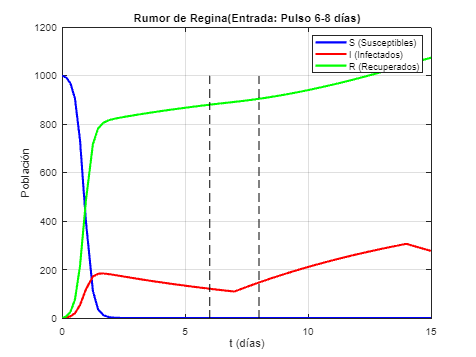

% Parámetros
beta = 0.03; gamma = 0.1; rho = 0.2; alpha = 0;
N = 1000; I0 = 1; R0 = 0; S0 = N - I0;
Days = 15;
t = 0:0.01:Days;
u_pulse = zeros(size(t)); 
start_pulse_day = 6;  
end_pulse_day = 8;
u_pulse(t >= start_pulse_day & t <= end_pulse_day) = 50;
inputData.time = t';
inputData.signals.values = u_pulse';
inputData.signals.dimensions = 1;
u = inputData;
out = sim('entradas.slx', Days);

% Grafica
figure;
plot(out.tout, out.sus.Data, 'b', 'LineWidth', 2);
hold on;
grid on;
plot(out.tout, out.inft.Data, 'r', 'LineWidth', 2);
plot(out.tout, out.recover.data, 'g', 'LineWidth', 2);

line([start_pulse_day, start_pulse_day], [0, max(out.sus.Data)], 'Color', 'k', 'LineStyle', '--', 'LineWidth', 1);
line([end_pulse_day, end_pulse_day], [0, max(out.sus.Data)], 'Color', 'k', 'LineStyle', '--', 'LineWidth', 1);

xlabel('t (días)');
ylabel('Población');
legend({'S (Susceptibles)', 'I (Infectados)', 'R (Recuperados)'});
title("Rumor de Regina(Entrada: Pulso 6-8 días)");
hold off;

## Entrada escalón

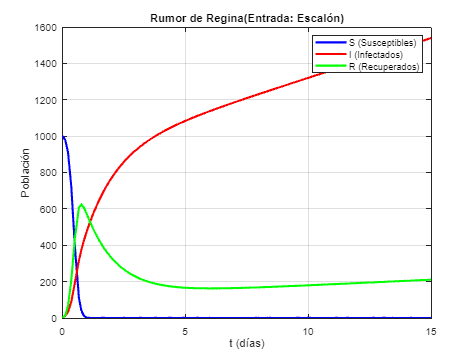

% Parámetros
beta = 0.03; gamma = 0.1; rho = 0.2; alpha = 0.7;
N = 1000; I0 = 1; R0 = 0; S0 = N-I0;
Days = 15;
t = 0:0.01:Days;
u_step = zeros(size(t));
start_step = 0;
u_step(t >= start_step) = 50;
inputData.time = t';
inputData.signals.values = u_step';
inputData.signals.dimensions = 1;
u = inputData;
out = sim('entradas.slx',Days);
figure;
plot(out.tout, out.sus.Data, 'b', 'LineWidth', 2);
hold on;
grid on;
plot(out.tout, out.inft.Data, 'r', 'LineWidth', 2);
plot(out.tout, out.recover.data, 'g', 'LineWidth', 2);
xlabel('t (días)');
ylabel('Población');
legend({'S (Susceptibles)', 'I (Infectados)', 'R (Recuperados)'});
title("Rumor de Regina(Entrada: Escalón)");
hold off;

**Señalización escalón:**

Al igual que en el pulso esto se hace para que el lector entienda en qué parte está, solo por fines metodológicos.

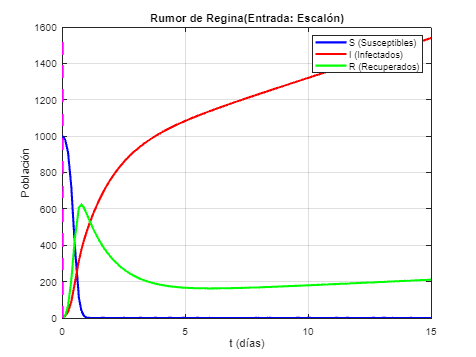

% Parámetros
beta = 0.03; gamma = 0.1; rho = 0.2; alpha = 0.7;
N = 1000; I0 = 1; R0 = 0; S0 = N - I0;
Days = 15;
t = 0:0.01:Days;
u_step = zeros(size(t));
start_step = 0;
u_step(t >= start_step) = 50;
inputData.time = t';
inputData.signals.values = u_step';
inputData.signals.dimensions = 1;
u = inputData;
out = sim('entradas.slx',Days);
% Grafica
figure;
plot(out.tout, out.sus.Data, 'b', 'LineWidth', 2);
hold on;
grid on;
plot(out.tout, out.inft.Data, 'r', 'LineWidth', 2);
plot(out.tout, out.recover.data, 'g', 'LineWidth', 2);
line([start_step, start_step], [0, max(out.inft.Data)], 'Color', 'm', 'LineStyle', '--', 'LineWidth', 3);
xlabel('t (días)');
ylabel('Población');
legend({'S (Susceptibles)', 'I (Infectados)', 'R (Recuperados)'});
title("Rumor de Regina(Entrada: Escalón)");
hold off;

# **Cambio parámetros**

**Para esta simulación no utilizamos entrada para ver como cambiabamos los parámetros con respecto a la simulación orginal, además de que los parámetros elegidos no suelen estar presente en el modelo SIR común, sino que es algo nuevo para este tipo de formas de modelar rumores.**

*Además se gráfican de dos formas diferentes, para que el lector del informe tenga una visión más clara, y quien vea el código pueda analizar con más facilidad.*

## **Para alpha (α)**

Versión lector Livescript

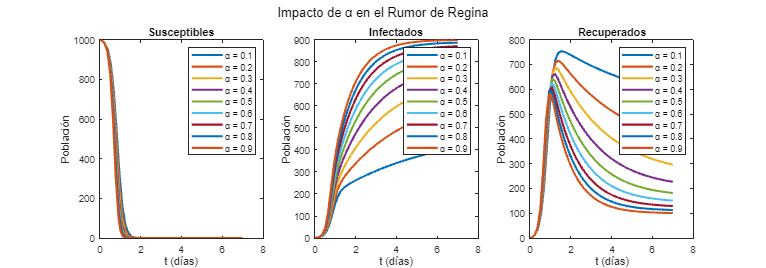

% Parámetros
beta = 0.03; gamma = 0.1; rho = 0.2;
N = 1000; I0 = 1; R0 = 0; S0 = N - I0;
Days = 7;

alpha_values = 0.1:0.1:0.9;

figure;
sgtitle('Impacto de α en el Rumor de Regina'); 

for i = 1:length(alpha_values)
    alpha = alpha_values(i);
    out = sim('modelo_verificado.slx', Days);
    subplot(1, 3, 1); 
    plot(out.tout, out.simS.Data, 'LineWidth', 2);
    hold on;
    title('Susceptibles');
    xlabel('t (días)');
    ylabel('Población');
    legendInfo{i} = ['α = ', num2str(alpha)];
    subplot(1, 3, 2); 
    plot(out.tout, out.simI.Data, 'LineWidth', 2);
    hold on;
    title('Infectados');
    xlabel('t (días)');
    ylabel('Población');
    legendInfo{i} = ['α = ', num2str(alpha)];
    subplot(1, 3, 3);
    plot(out.tout, out.simR.Data, 'LineWidth', 2);
    hold on;
    title('Recuperados');
    xlabel('t (días)');
    ylabel('Población');
end

for i = 1:3
    subplot(1, 3, i);
    legend(legendInfo, 'Location', 'NorthEast');
end

set(gcf, 'Position', [100, 100, 2000, 700]);

hold off;

Versión para el informe

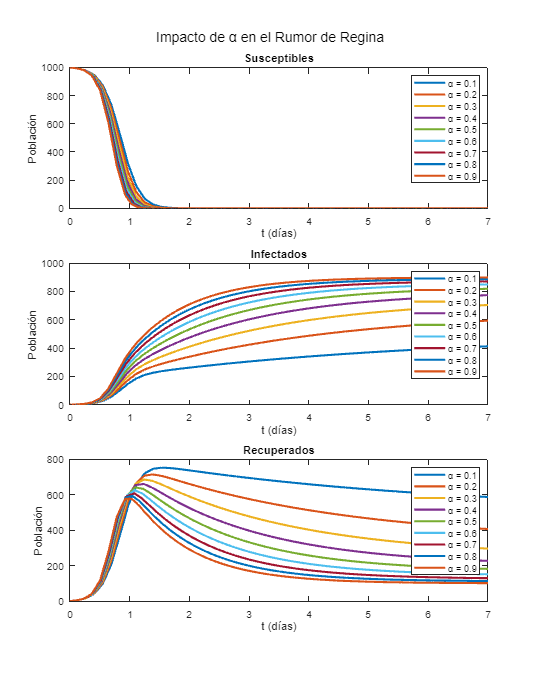

% Parámetros
beta = 0.03; gamma = 0.1; rho = 0.2;
N = 1000; I0 = 1; R0 = 0; S0 = N - I0;
Days = 7;

alpha_values = 0.1:0.1:0.9;

figure;
sgtitle('Impacto de α en el Rumor de Regina'); 

for i = 1:length(alpha_values)
    alpha = alpha_values(i);
    out = sim('modelo_verificado.slx', Days);
    subplot(3, 1, 1); 
    plot(out.tout, out.simS.Data, 'LineWidth', 2);
    hold on;
    title('Susceptibles');
    xlabel('t (días)');
    ylabel('Población');
    legendInfo{i} = ['α = ', num2str(alpha)];
    subplot(3, 1, 2); 
    plot(out.tout, out.simI.Data, 'LineWidth', 2);
    hold on;
    title('Infectados');
    xlabel('t (días)');
    ylabel('Población');
    legendInfo{i} = ['α = ', num2str(alpha)];
    subplot(3, 1, 3);
    plot(out.tout, out.simR.Data, 'LineWidth', 2);
    hold on;
    title('Recuperados');
    xlabel('t (días)');
    ylabel('Población');
end

for i = 1:3
    subplot(3, 1, i);
    legend(legendInfo, 'Location', 'NorthEast');
end

set(gcf, 'Position', [100, 100, 800, 1000]);

hold off;

## Para rho (ρ)

Versión lector Livescript

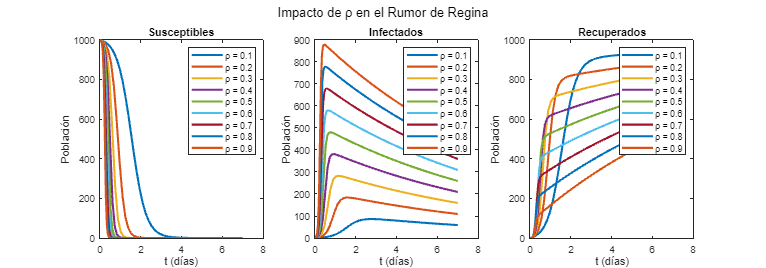

% Parámetros
beta = 0.03; gamma = 0.1; alpha = 0.;
N = 1000; I0 = 1; R0 = 0; S0 = N - I0;
Days = 7;

rho_values = 0.1:0.1:0.9;

figure;
sgtitle('Impacto de ρ en el Rumor de Regina'); 

for i = 1:length(rho_values)
    rho = rho_values(i);
    out = sim('modelo_verificado.slx', Days);
    subplot(1, 3, 1);
    plot(out.tout, out.simS.Data, 'LineWidth', 2);
    hold on;
    title('Susceptibles');
    xlabel('t (días)');
    ylabel('Población');
    legendInfo{i} = ['ρ = ', num2str(rho)]; 
    subplot(1, 3, 2);
    plot(out.tout, out.simI.Data, 'LineWidth', 2);
    hold on;
    title('Infectados');
    xlabel('t (días)');
    ylabel('Población');
    legendInfo{i} = ['ρ = ', num2str(rho)];
    subplot(1, 3, 3);
    plot(out.tout, out.simR.Data, 'LineWidth', 2);
    hold on;
    title('Recuperados');
    xlabel('t (días)');
    ylabel('Población');
    legendInfo{i} = ['ρ = ', num2str(rho)]; 
end

for i = 1:3
    subplot(1, 3, i);
    legend(legendInfo, 'Location', 'NorthEast'); 
end

set(gcf, 'Position', [100, 100, 2000, 700]);
hold off;

Versión para informe

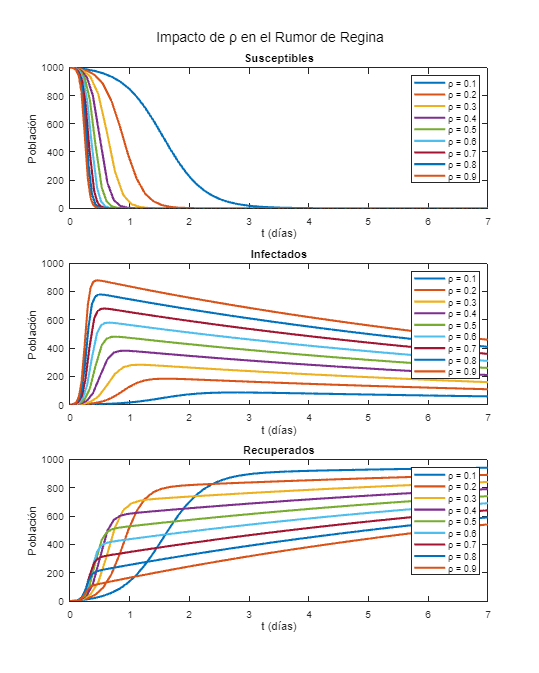

% Parámetros
beta = 0.03; gamma = 0.1; alpha = 0.;
N = 1000; I0 = 1; R0 = 0; S0 = N - I0;
Days = 7;

rho_values = 0.1:0.1:0.9;

figure;
sgtitle('Impacto de ρ en el Rumor de Regina'); 

for i = 1:length(rho_values)
    rho = rho_values(i);
    out = sim('modelo_verificado.slx', Days);
    subplot(3, 1, 1);
    plot(out.tout, out.simS.Data, 'LineWidth', 2);
    hold on;
    title('Susceptibles');
    xlabel('t (días)');
    ylabel('Población');
    legendInfo{i} = ['ρ = ', num2str(rho)]; 
    subplot(3, 1, 2);
    plot(out.tout, out.simI.Data, 'LineWidth', 2);
    hold on;
    title('Infectados');
    xlabel('t (días)');
    ylabel('Población');
    legendInfo{i} = ['ρ = ', num2str(rho)];
    subplot(3, 1, 3);
    plot(out.tout, out.simR.Data, 'LineWidth', 2);
    hold on;
    title('Recuperados');
    xlabel('t (días)');
    ylabel('Población');
    legendInfo{i} = ['ρ = ', num2str(rho)]; 
end

for i = 1:3
    subplot(3, 1, i);
    legend(legendInfo, 'Location', 'NorthEast'); 
end

set(gcf, 'Position', [100, 100, 800, 1000]);
hold off;